tic

if ~exist("colorset")
    load colorset.mat
end
% Step 1: Set order of the stacking area plot
% Usually show baseloads first, the peakings are on top
% Set a type's order to 0 to remove it from the figure

% select a year for the plot
yr = 2022;

filepath = fileparts(pwd);
load(filepath + sprintf("\\data\\fuelmix%4d",yr));

varGen = setdiff(fuelmix.Properties.VariableNames,{'SETTLEMENTDATE','PHSpump','RRP'})

varGen = 1×11 cell array
    {'Bio'}    {'Coal'}    {'Gas'}    {'HydroRunofriverAndPoundage'}    {'HydroWaterReservoir'}    {'Nuclear'}    {'Oil'}    {'PHSgen'}    {'Solar'}    {'Waste'}    {'Wind'}


% new variable names for data from fuelmix
gen = fuelmix(:,varGen);
gen.Properties.VariableNames = colorset.types(1:11);

loads = fuelmix(:,'PHSpump');
loads.Properties.VariableNames = colorset.types(12);


% colorset is sorted by your order setting. 
% If a type's order is zero, it will be removed (won't be shown on the figure)
stackorder = sortrows(colorset,"order");
stackorder = stackorder(stackorder.order ~= 0,:);

% Sort the gen, demand data according to the order that you have set.
gen = gen(:,stackorder.types(ismember(stackorder.types,gen.Properties.VariableNames)));
loads = loads(:,stackorder.types(ismember(stackorder.types,loads.Properties.VariableNames)));

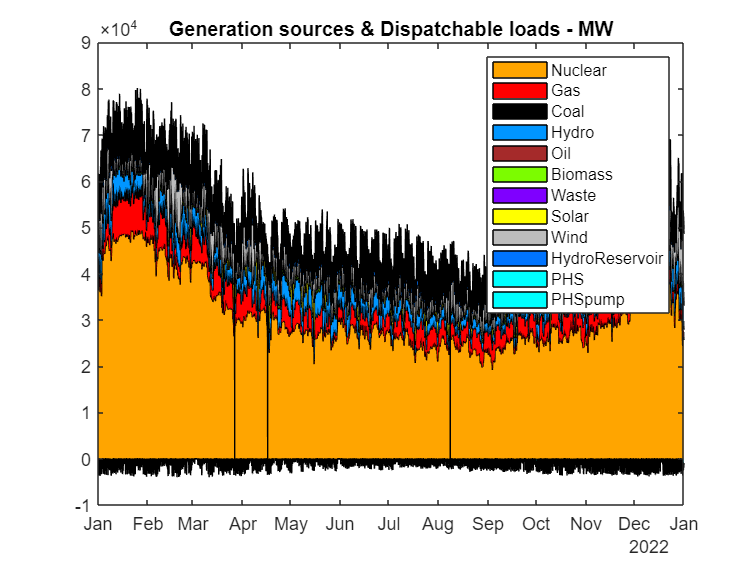

% plot
clf
area(fuelmix.SETTLEMENTDATE,gen.Variables)
hold on
area(fuelmix.SETTLEMENTDATE,-loads.Variables)
colororder(stackorder.color)
legend(stackorder.types)
% xticks(fuelmix.SETTLEMENTDATE(144:144:height(gen)))
title('Generation sources & Dispatchable loads - MW')

% 
% xlim([datetime(2022,12,14,12,0,22)...
%       datetime(2022,12,17,20,28,40)])
% ylim([-10000 90000])

toc

Elapsed time is 1.798033 seconds.


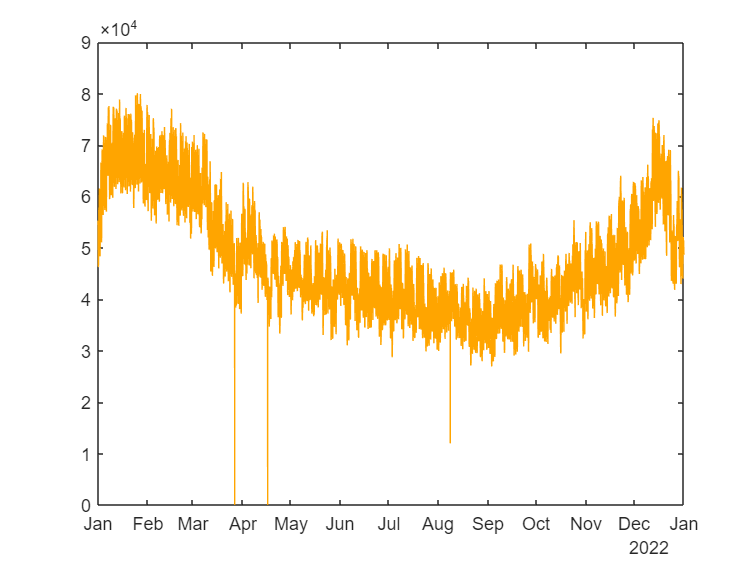

clf
plot(fuelmix.SETTLEMENTDATE,sum(gen.Variables,2)-sum(loads.Variables,2))

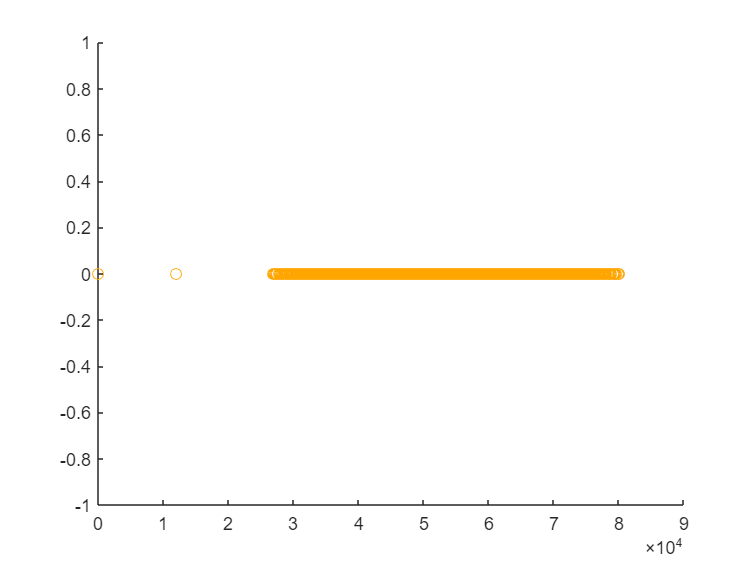

clf
scatter(sum(gen.Variables,2)-sum(loads.Variables,2),fuelmix.RRP)